# Why does L1 regularization (LASSO) tend to give sparse solutions?

Consider the least squares problem to solve for the regression weights $w_0, w=[w_1,\ldots,w_m]^T$ in the linear model $f(x; w_0, w)$, where $(x_i, y_i)$, $i=1,\ldots,n$ is the data:

$\min_w \sum_i (y_i - f(x_i; w_0, w))^2$.

To constrain the solution to be small in size, we can add the constraint $\|w\|_1 \le \eta$, where $\eta$ is a parameter. This will tend to give solutions $w$ that are *sparse*, i.e., many components of $w$ will tend to be zero.

This type of regularized regression is called LASSO, which stands for Least Absolute Shrinkage and Selection Operator. Shrinkage is a term from statistics that refers to regularization, a method that tries to reduce the "shrinkage" of the test MSE compared to the training MSE. Selection refers to the selection of features associated with nonzero weights, these being the weights that are important in the regression, while the others are not important.

To understand why this 1-norm constraint tends to give sparse solutions, we will *simulate* solving the constrained minimization problem in two dimensions ($w$ has two components, $w_1$ and $w_2$).

First notice that the unconstrained objective function is quadratic in $w$, a fixed value of this function is traced by an ellipse in the plane of $w_1$ and $w_2$. Then, to find the solution that satisfies the 1-norm constraint, we want to find the *smallest* ellipse that touches the constraint boundary, which has a diamond shape. The point where the ellipse touches the constraint boundary is the solution that we desire. We will see that this solution is tends to touch the corners of the diamond, which means that one of the two components of $w$ is zero at the solution.

Without loss of generality, we assume $\eta=1$. The points in the $w_1, w_2$ plane that satisfy $\|w\|_1 \le 1$ is called the 1-norm ball. We first draw this ball.

% plot the 1-norm ball
clf
r = 1;
plot([ 0  r],[ r  0],'k');
hold on
plot([ r  0],[ 0 -r],'k');
plot([ 0 -r],[-r  0],'k');
plot([-r  0],[ 0  r],'k');
axis equal;
axis([-3 3 -3 3]);

When you run this demo, a figure window will pop up. Use the slider to adjust the size of the ellipse, until the ellipse touches the 1-norm ball. Press the *Restart* button to try a new ellipse. The next few lines of code will set up this user interface and define a circle of points that we will stretch, rotate, and translate to a random position, corresponding to an arbitrary unconstrained least-squares problem (which would depend on the given data). 

% set up user interface
slider = uicontrol('Style','slider', 'Min',0, 'Max',4, 'Callback',@slider_callback);
button = uicontrol('Style','pushbutton', 'String','Restart', 'Callback', @button_callback);
slider.Position = [1 1 600 30];
button.Position = [1 31 50 30];

% predefine circle of points to be stretched into ellipse
xx = linspace(0, 2*pi, 50)';
pointsx = cos(xx);
pointsy = sin(xx);
% get handle of ellipse
hplot = plot(0*pointsx, 0*pointsy, 'r-');

The demo looks something like this:

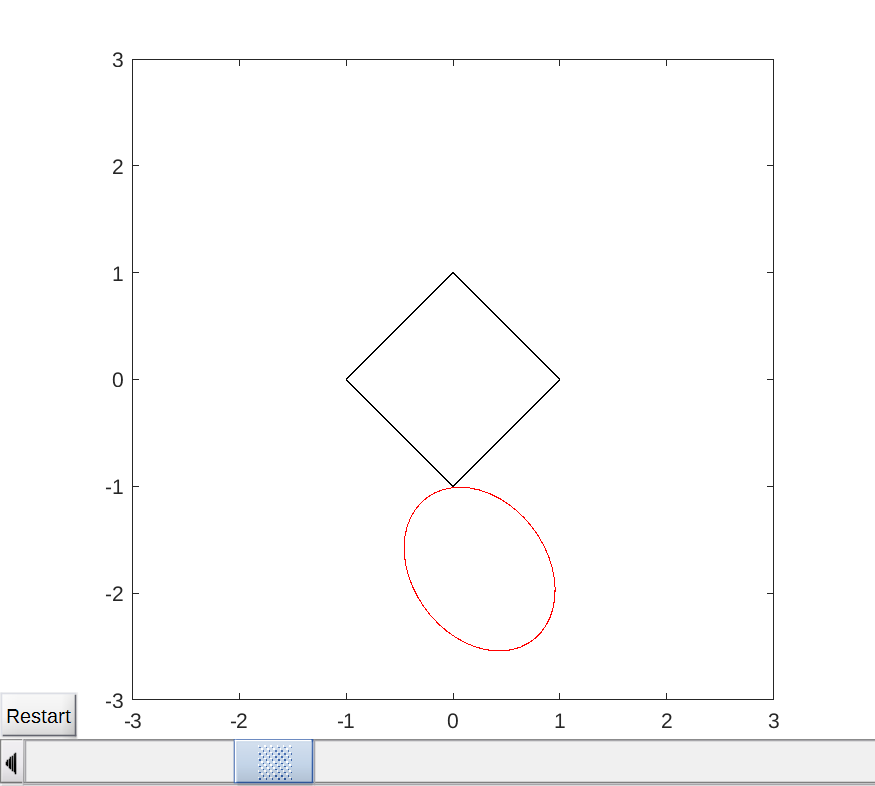

The rest of the code is a user-interface loop. When we start or restart, the new ellipse is chosen. An inner loop captures movements of the slide and adjusts the size of the ellipse accordingly.

while 1
  % choose center not too close to origin (outside of 1-norm ball)
  while 1
    p = (rand(2,1)-.5)*5;
    if norm(p) > 1.5, break; end
  end
  center_x = p(1);
  center_y = p(2);
  
  % random length of semi-axes
  p = rand(2,1) + 0.1; % avoid very narrow ellipses
  p = p/norm(p); % avoid very small ellipses
  semi_xlen = p(1);
  semi_ylen = p(2);
  
  % random rotation matrix
  angle = rand*2*pi;
  R = [cos(angle) sin(angle); -sin(angle) cos(angle)];
  
  % stretch and rotate circle
  points = [semi_xlen*pointsx semi_ylen*pointsy] * R;
  
  global restart
  restart = 0;
  prev = 0;
  slider.Value = 0.1;
  while restart == 0
    val = slider.Value;
    if val == prev
      pause(0.1);
    else
      hplot.XData = val*points(:,1)+center_x;
      hplot.YData = val*points(:,2)+center_y;
      prev = val;
    end
  end
  % remove ellipse
  hplot.XData = 0*points(:,1);
  hplot.YData = 0*points(:,2);
end

The following are two callback functions we need for the user interface.

function button_callback(button, ~, ~)
global restart
restart = 1;
end

% need to have a dummy callback function for value to be updated
function slider_callback(slider, ~, ~)
end

Close the window when you are done (otherwise the demo will keep running).

### Taking it further

Out of 10 tries, how many times did you typically find a sparse solution? Do you think that this probability will be higher or lower for a higher dimensional problem (more than 2 dimensions)? In 3 dimensions, for example, the 1-norm ball is a 3-dimensional diamond shape, and 2 components of $w$ will be zero if the ellipsoid touches a corner, and 1 components will be zero if the ellipsoid touches an edge.